# MODEL SETUP

% Clear workspace and initialize parameters
close all;
clear all;

% % System parameters
model.m = 1;            % Mass (kg)
model.c = 0.05;         % Damping coefficient (Ns/m)
model.k = 10;           % Stiffness (N/m)
model.alpha = 1;        % Nonlinear stiffness coefficient (N/m^3)

## Open loop parameters

% User Input parameters
input.a = 0;                % acos(wt)
input.b = 1;                % + bsin(wt)
input.w0 = 2 * pi;          % Forcing frequency (rad/s)
input.T = (2*pi)/input.w0;
input.b_history = [input.b];

% Prepare trial variable history
trial.t = [];
trial.X = [];

% Trial init parameters
trial.x_init = [0, 0];
trial.t_init = 0;

trial.periods = 150;
trial.t_span = [0, trial.periods*input.T];

trial.harmonics = 7; %number of harmonics of interest when estimating response amplitude

## OPEN LOOP TEST STEP:

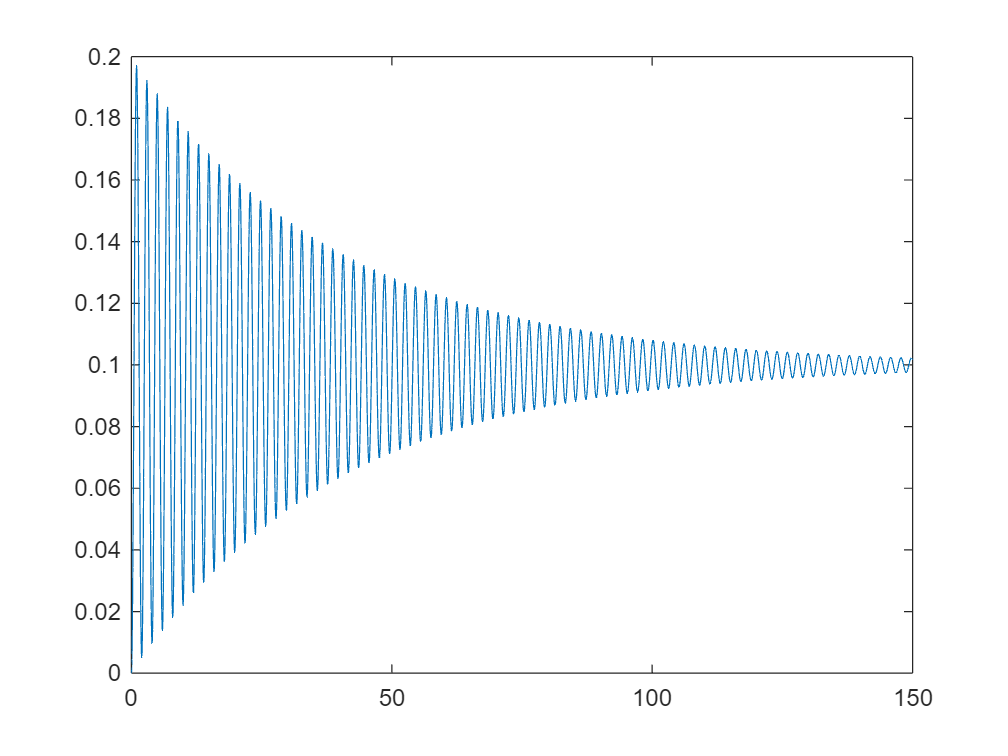

% Simulation loop --------------------------------------------------------
p_external = @(t) 1;
% Define ODE function
odefun = @(t, X) [X(2); 
                  (1 / model.m) * (p_external(t) - model.c * X(2) - model.k * X(1) - model.alpha * X(1)^3)];

% Simulate between time steps
[trial.t, trial.X] = ode45(odefun, trial.t_init + [trial.t_span(1), trial.t_span(end)], trial.x_init);

figure;
plot(trial.t, trial.X(:, 1))

## OPEN LOOP TEST AT SPECIFIC FORCING

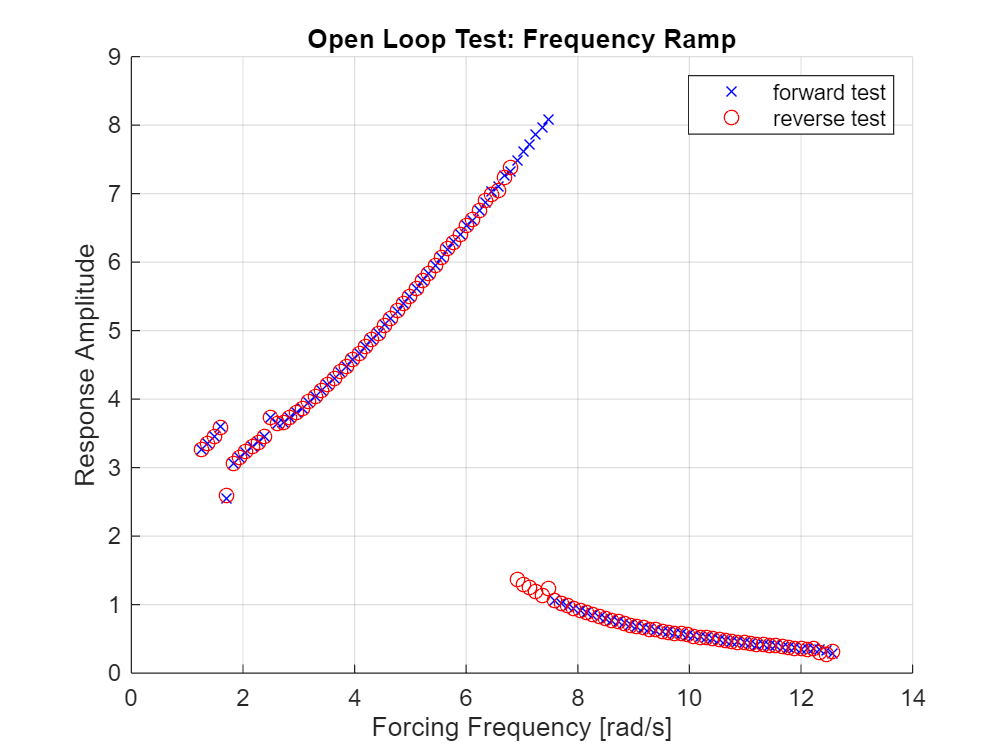

max_freq = 2*2*pi;
min_freq = 0.2*2*pi;
input.b = 50;
%-------------- OPEN LOOP RAMP ---------------------%
trial.x_init = [0, 0];
trial.t_init = 0;

freq_vals = linspace(min_freq, max_freq, 101);
response_vals = zeros(size(freq_vals));

t_history = []; % (nx1)
x_history = []; % (nx1)

for i = (1:length(freq_vals))
    input.w0 = freq_vals(i);          % Forcing frequency (rad/s)
    input.T = (2*pi)/input.w0;
    trial.t_span = [0, trial.periods*input.T];

    trial = openloop_test(model, input, trial);
    response_vals(i) = trial.ss_response_amp;
    % x_history = [x_history; trial.X(:, 1)];
    % t_history = [t_history; trial.t];
end
%-------------- OPEN LOOP RAMP REVERSE ---------------------%
trial.x_init = [0, 0];
trial.t_init = 0;

freq_vals2 = freq_vals(end:-1:1);     % reverse of previous
response_vals2 = zeros(size(freq_vals2));

t_history2 = []; % (nx1)
x_history2 = []; % (nx1)

for i = (1:length(freq_vals2))
    input.w0 = freq_vals2(i);          % Forcing frequency (rad/s)
    input.T = (2*pi)/input.w0;
    trial.t_span = [0, trial.periods*input.T];

    trial = openloop_test(model, input, trial);
    response_vals2(i) = trial.ss_response_amp;
    % x_history2 = [x_history2; trial.X(:, 1)];
    % t_history2 = [t_history2; trial.t];
end

%plotting
figure;
hold on;
grid on;
plot(freq_vals, response_vals, 'bx');
plot(freq_vals2, response_vals2, 'ro');
xlabel("Forcing Frequency [rad/s]");
ylabel("Response Amplitude");
title("Open Loop Test: Frequency Ramp");
legend(["forward test", "reverse test"], "Location","northeast");

## OPEN LOOP TEST: Response ampl vs forcing amp

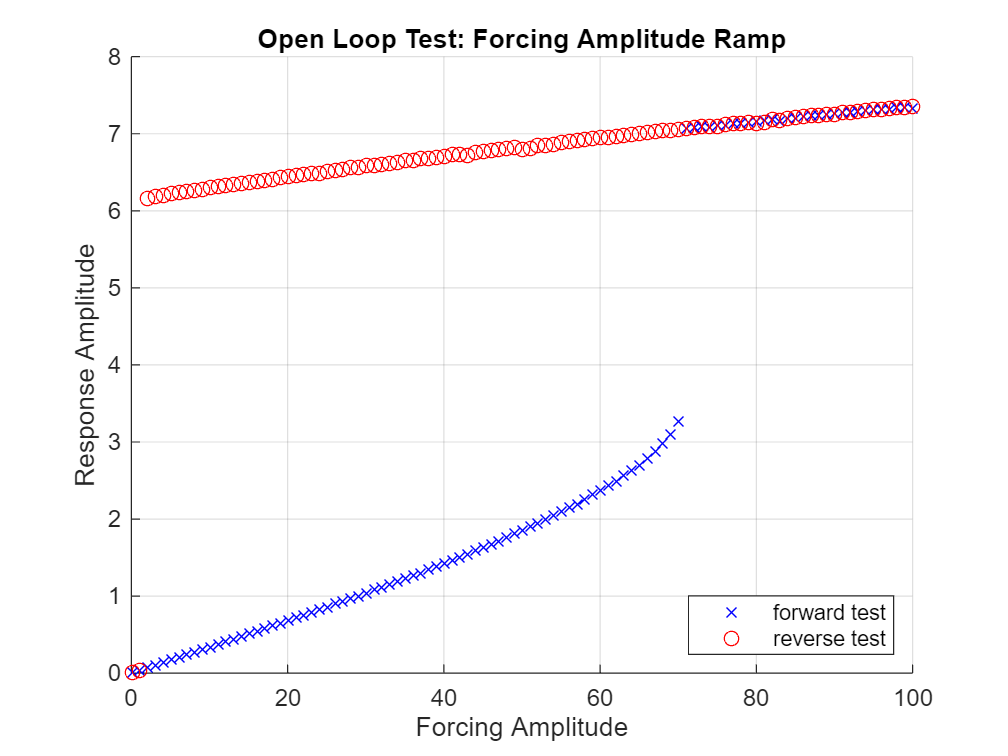

% RESET FREQ
input.w0 = 2 * pi;          % Forcing frequency (rad/s)
input.T = (2*pi)/input.w0;


max_force = 100;
min_force = 0.1;

%-------------- OPEN LOOP RAMP ---------------------%
trial.x_init = [0, 0];
trial.t_init = 0;

forcing_vals = linspace(min_force, max_force, 101);
response_vals = zeros(size(forcing_vals));

t_history = []; % (nx1)
x_history = []; % (nx1)

for i = (1:length(forcing_vals))
    input.b = forcing_vals(i);
    trial = openloop_test(model, input, trial);
    response_vals(i) = trial.ss_response_amp;
    % x_history = [x_history; trial.X(:, 1)];
    % t_history = [t_history; trial.t];
end
%-------------- OPEN LOOP RAMP REVERSE ---------------------%
trial.x_init = [0, 0];
trial.t_init = 0;

forcing_vals2 = forcing_vals(end:-1:1);     % reverse of previous
response_vals2 = zeros(size(forcing_vals));

t_history2 = []; % (nx1)
x_history2 = []; % (nx1)

for i = (1:length(forcing_vals2))
    input.b = forcing_vals2(i);
    trial = openloop_test(model, input, trial);
    response_vals2(i) = trial.ss_response_amp;
    % x_history2 = [x_history2; trial.X(:, 1)];
    % t_history2 = [t_history2; trial.t];
end

%plotting
figure;
hold on;
grid on;
plot(forcing_vals, response_vals, 'bx');
plot(forcing_vals2, response_vals2, 'ro');
xlabel("Forcing Amplitude");
ylabel("Response Amplitude");
title("Open Loop Test: Forcing Amplitude Ramp");
legend(["forward test", "reverse test"], "Location","southeast");